# Sensory coding practical

## Before you begin...

This is a live script document that you can open and run in Matlab. This document contains both explanation text for the practical as well as the Matlab code for the data analysis. In this way can run the analysis as you go and analyze your files during the practical. Here are some important things you have to know before you start:

- The code is written in small sections, so that you can easily understand what you do and run it section by section. You can recognize the section limits by blue lines around the section. If you click on the code within the section you are in! 

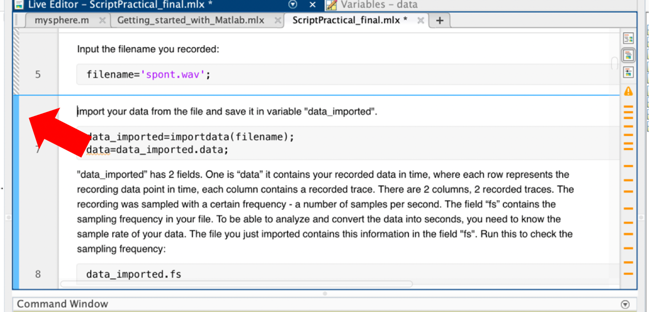

- Now you can run the code in the section by pressing the button "Run Section". 

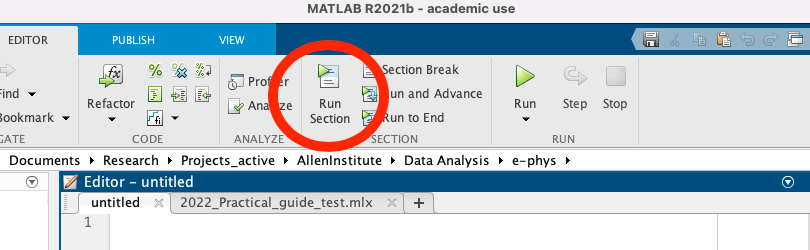

- Do not press "Run", it will execute all the code in the scirpt, take a lot of time and generate a lot errors because of still missing data. If this still happens by accident, go back to the section of the code you were working on and proceed from there (as you go further you will rerun the code with the correct variables and the errors will disappear). 

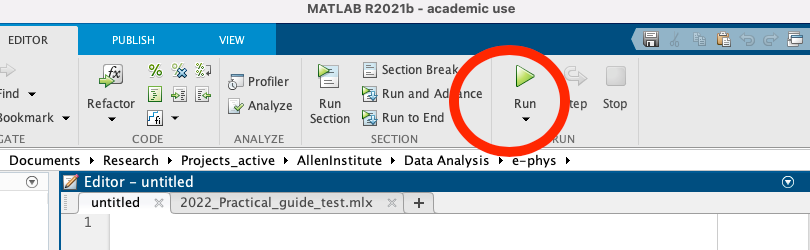

- Be careful to change the names of the files you analyze and the figures you are going to save for the report. 

- There are questions that you will have to answer during the practical. Don't forget to save your answers to the questions, you will need them for  your report. You can also just type your answers in the text below the quesitons in this file and save this file as .mlx file and .docx file at the end of the practical. In this way you will be able to see later what you have done during the practical and rerun the script if you want.

- At the end of the practical don't forget to copy the folder with your analysis, figures and recordings to your own memory device or upload on your cloud drive.

You are set to go! 

## Part 1: Recording Spontaneous Action Potentials 

### Preparation 

- Get the cockroach leg from pracitcal assistant and mount it on the amplifier (Backyard Brains Neuron Spikerbox pro). Clean your electrodes. Insert the ground electrode (black pin) into the femur, piercing it into the underlying corkboard. Insert the recording electrode (white pin) into the coxa.  

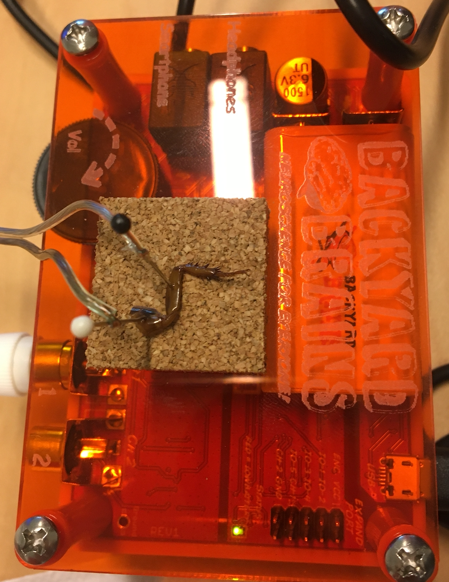

- Plug in the USB connector to laptop and turn on the amplifier by turning the black volume knob:

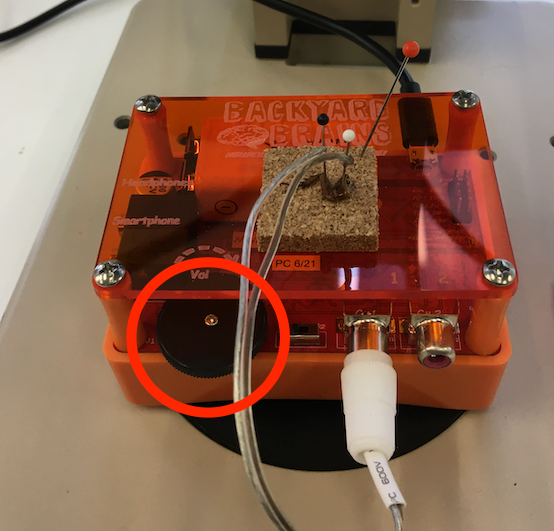

- Open the Spike Recorder software.

- Click the top left usb icon to connect to amplifier  

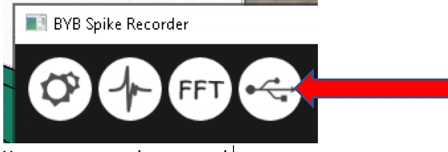

- You are now ready to record s**pontaneous activity **of axonal fibers in cockroach's leg

- In a high-quality recording you will clearly hear spontaneous action potentials through the speaker. It should sound like raindrops hitting a window over a quiet background noise. You will also be able to see spikes on the Spike Recorder oscilloscope window.

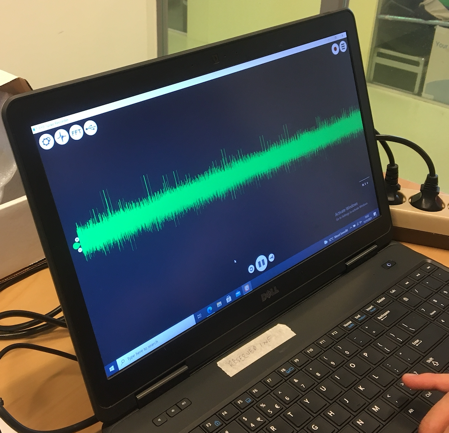

- If you cannot see and hear the spikes, try placing your electrodes at different locations in the coxa and femur.

- If you still cannot see and hear the spikes after a few electrode placements, ask the TA for another leg.

- Record action potentials for about 10s using the top right record button. 

- Rename the file "spont" *(.wav is the extension of the file, it is added to the file automatically).*

### Step 1. Import data and plot the spontaneous signal

Close all figures and clean the variables from your workspace and start with an empty workspace:

clear all
close all

Define here the path to the folder in which you are working on the computer. If you are going to rerun the analysis on your own computer, don't forget to put all the files in one folder and specify here the path to this folder:

folder='/Users/....';
addpath(genpath(folder));

Input the filename you recorded (make sure the name of the recorded file is *exactly the same* as in the code). 

filename='spont.wav'; 

import your data from the file and save it in variable "data_imported". If you get an error here, it is most probably because the folder name to the files or the name of the file do not match with the real names. Check folder and file name again.

data_imported=importdata(fullfile(folder,filename));

To your right, in Workspace panel, you can now see the created variables, if you click on the variable it will appear in a "Variables" tab and you can examine it.  "data_imported” has 2 fields. One is “data” it contains your recorded data in time, where each row represents the recording data point (sample) in time. In the example below, there is 1 column, 1 recorded trace with 109213 samples.

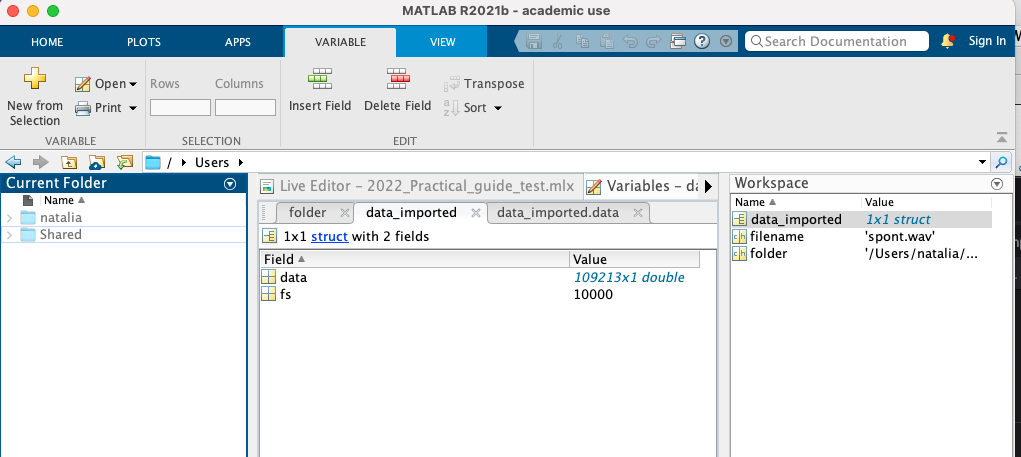

The recording was sampled with a certain frequency - a number of samples per second. The field “fs” contains the sampling frequency in your file. To be able to analyze and convert the data into seconds, you need to know the sampling rate of your data. In the example below you can see the recording in samples (shown as blue circles). In this example, there are 100 samples in a 10 ms long recording, so the sampling frequency is 10 000 samples in a second, or 10 000 Hz.

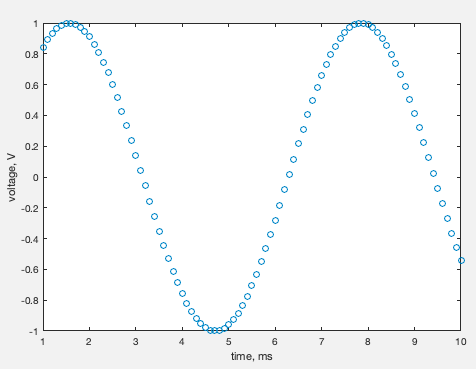

The file you just imported contains this information in the field "fs". Run this to check the sampling frequency:

data_imported.fs

You can see that the sampling rate is 10000 Hz or 10 kHz. Save it as a variable "srate":

srate=data_imported.fs;

Save your data as a variable "data":

data=data_imported.data;
% we will not need data_imported anymore, so we clear it
clear data_imported

How many rows does your data variable have? how long was the recording?

We will cut the data file to the nearest full second, e.g if your file is 10.564 s long, we will cut it to exactly 10 s long. This will help us when we will devide the file in 1s bins to calculate spike frequency.

data=data(1:floor(size(data,1)/srate)*srate,:); 
trace=data(:,1);

Create a new variable “x” that contains the data corresponding to the time of each sample in seconds, in this way we will be able to plot the data in seconds.

x=(1:size(data,1))/srate;

Now we will create a figure and plot the trace:

h=figure;
plot(x,trace);

Add y and x axis labels and the title. 

hold on;
ylabel('Voltage,mV');
xlabel('Time, s')
title(filename);

**Optional!**

If most of the spikes are negative (facing downwards in the plot), you can run the following code to reverse your trace for futher analysis:

trace=-data(:,1); % reverse polarity if needed 

Rerun the code for plotting the data to check if the spikes are now positive.

### Step 2. Analyze the trace: extract the spikes

Now that we have imported the trace, we can start the analysis and extract spikes (action potentials). First find the peaks of action potentials by using the function "findpeaks". If you get a warning like this:

It means that your threshold for defining peaks is too high and no spike were detected. The reason for this is that your recording most probably does not contain spikes or the threshold value is too high. Try to make a new recording of sponaneous activity.

clear locs % in case locs already exist clear it
amp_threshold=0.05; 
[~,locs]=findpeaks(trace,'MinPeakHeight',amp_threshold,'MinPeakDistance',3);

If in your signal the spikes are negative you can reverse the signal of the trace by running this code in the command line below: 

trace=-trace;

Plot the trace and mark all action potentials (peaks) with a red circle:

plot(x, trace,'b');
hold on
plot(x(locs),trace(locs),'ro'); 
hold off

You can play with the settings and zoom in a part of the trace to better see the spikes. We will do it by defining the interval of the trace to plot. 

%define here the start and end of the interval to plot (in samples) 
start_interval=5000; 
end_interval=7000;

interval=[start_interval:end_interval]; 
% plot the interval
plot(x(interval),trace(interval),'b');
hold on;
ylabel('Voltage,mV'); 
xlabel('Time,s');
title('Trace with action potentials');

% select only the peak indices that fit within the interval
newlocs=locs(locs>start_interval & locs<end_interval);

% plot the spike peaks with red circle
plot(x(newlocs),trace(newlocs),'ro');
hold off

Now we can tune our analysis. Since the threshold for detecting the spikes is different for each recording conditions, you can play with the amplitude settings to define the minimum peaks. In your analysis you want to avoid mistaking noise for spikes on the one hand, but also missing the small spikes. The default amplitude is 0.05. Change the threshold value. What happens with the detection of peaks if you increase or decrease this threshold value?

clear locs % in case locs already exist clear it
amp_threshold=0.05; %change amplitude threshold here!
[~,locs]=findpeaks(trace,'MinPeakHeight',amp_threshold,'MinPeakDistance',3);
plot(x, trace,'b');
hold on
plot(x(locs),trace(locs),'ro');
hold off

Choose the best interval to plot:

%define here the start and end of the interval to plot (in samples) 
start_interval=2000; 
end_interval=3000;
interval=[start_interval:end_interval]; 
% plot the interval
plot(x(interval),trace(interval),'b');
hold on;
ylabel('Voltage,mV'); 
xlabel('Time,s');
title('Trace with action potentials');
% select only the peak indices that fit within the interval
newlocs=locs(locs>start_interval & locs<end_interval);

% plot the spike peaks with red circle
plot(x(newlocs),trace(newlocs),'ro');
hold off

When you found the optimal threshold and time window, save the figure. Enter the name for the saved figure in control field, replace xxx with your own name:

% if you don't have a folder, make a folder here called 'Figures' for saving your figures
if not(isfolder(fullfile(folder,'Figures')))
    mkdir(fullfile(folder,'Figures'))
end
saveas(h,fullfile(folder,'Figures','Fig1_xxx.jpeg')); % Now your figure is in the folder Figures

Check if the figure was saved.

***Q1: What ions cause the phases of the action potential? ***

### Step 3. Frequency of firing

Let's find out what the average frequency of firing is in your trace. To do this you need to divide the number of spikes in the trace by the duration of the trace. Try to estimate by eye the frequency in your recording, is it similar to the calculated mean_freq?

mean_freq=size(locs,1)/max(x); % this will give you a number of spikes per second

***Q2: What is the average firing frequency in your recording?***

Plot firing frequency in your recording as a function of time:

h2=figure;
histogram(x(locs),size(trace,1)/(1*srate));
ylabel('spike freq, Hz');
xlabel('time, s');
saveas(h2,fullfile(folder,'Figures','Fig2_xxx.jpeg')); % save your figure here

***Q3: What might cause changes in frequency in your plot? ***

***Q4 What is the number of spikes in the first second? Is it similar to what you calculated previously with mean_freq?***

### Step 4. Spike amplitude

Now let's have a look at an average spike (waveform). We will extract the waveforms for all detected spikes and calculate the average waveform. We will plot the traces in the window of 20 samples, the traces for individual spikes are black, the average waveform is plotted in blue, standard deviation in shown in red lines.

wave=[];
window=20; % how many samples on either side of spike
for i=1:size(locs,1)
    if locs(i)>window
    wave(i,:)=trace([locs(i)-window:locs(i)+window]);
    end
end
wave(wave==0)=NaN;
wave_ave=mean(wave,1);
wave_std=std(wave,1);
h3=figure;
plot(wave(:,:)','k');
hold on
plot(wave_ave,'Color','b','LineWidth',3);
errorbar(wave_ave,wave_std, 'Color','r');
xlabel('Time, samples');
ylabel('Voltage,mV');
title('Average spike');
hold off

You can change the window to plot more or less samples around the peak and plot only the average trace:

wave=[];
window=20; % change the value of window here
for i=1:size(locs,1)
    if locs(i)>window
    wave(i,:)=trace([locs(i)-window:locs(i)+window]);
    end
end
wave(wave==0)=NaN;
wave_ave=[];
wave_std=[];
wave_ave=mean(wave,1,'omitnan');
wave_std=std(wave,1,'omitnan');
plot(wave_ave,'LineWidth',3);
hold on
errorbar(wave_ave,wave_std); % plot the sandard deviation of the average spike
hold off
xlabel('Time, samples');
ylabel('Voltage,mV');
title('Average spike');


***Q6: What is the interval between two samples (hint: remember the sampling frequency)? What is the half width at half height of the average spike?***

Save the figure for your report:

saveas(h3,fullfile(folder,'Figures','Fig3_xxx.jpeg'));

Now we find out what is the distribution of all amplitudes (maximum point of each waveform) in the recording and plot this distribution as histogram:

amp=max(wave,[],2);
h4=figure;
histogram(amp,20);
xlabel('Spike amplitude, mV');
ylabel('Count');
title('Amplitude histogram');

***Q7: What is the most frequent amplitude of the waveform?  Do you have multiple peaks in your distribution? What does it mean?***

Save the figure for your report:

saveas(h4,fullfile(folder,'Figures','Fig4_xxx.jpeg'));

### Step 5. Isolate different axons based on amplitude

If there are multiple amplitudes, we can try to isolate the separate axons with different characteristics based on the amplitude. Rerun the code for analyzing your trace and extracting spikes, but now change the threshold to only extract information on one axonal fiber with the biggest amplitudes.

clear locs % in case locs already exists, clear it and recalculate
amp_threshold= 0.07; %change amplitude threshold here!
[~,locs]=findpeaks(trace,'MinPeakHeight',amp_threshold,'MinPeakDistance',3);

mean_freq=size(locs,1)/max(x); % this will give you a number of spikes per second
h5=figure;
plot(x,trace);
hold on
ylabel('Voltage,mV'); 
xlabel('Time,s');
title('Trace with action potentials');
plot(x(locs),trace(locs),'ro');

Save the figure:

saveas(h5,fullfile(folder,'Figures','Fig5_xxx.jpeg'));

Plot now the spike shape and amplitude distribution for this new analysis:

wave=[];
window=20; % change the value of window here
for i=1:size(locs,1)
    if locs(i)>window
    wave(i,:)=trace([locs(i)-window:locs(i)+window]);
    end
end
wave(wave==0)=NaN;
wave_ave=mean(wave,1);
wave_std=std(wave,1);
% plot waverform
h6=figure; 
plot(wave_ave,'LineWidth',3);
hold on
errorbar(wave_ave,wave_std); % plot the sandard deviation of the average spike
hold off
xlabel('Time, samples');
ylabel('Voltage,mV');
title('Average spike');

Note: if you have no detected spikes in the recording, you will not be able to plot the spike shape. In that case, try to rerun the steps above with a lower threshold.

**Q8: Is the half width now different from previous analysis? **

 Save the figure:

saveas(h6,fullfile(folder,'Figures','Fig6_xxx.jpeg'));

Now plot the amplitude distribution for this new analysis. Is it different?

amp=max(wave,[],2);
h7=figure;
histogram(amp,20);
xlabel('Spike amplitude, mV');
ylabel('Count');
title('Amplitude histogram');

Save the figure:

saveas(h7,fullfile(folder,'Figures','Fig7_1xxx.jpeg')); % save your figures here

## **Part 2: Sensory stimulation**

### Step 1. Sensory encoding of leg flexion 

In this part we will activate the proprioceptors in the leg by changing the angle of the joint. We will analyze the differences in action potential firing at different positions of the leg.

- Use pins to set the femur-tibia joint at different angles. Make a short recording at each angle after you changed the position of the leg.

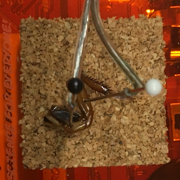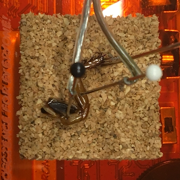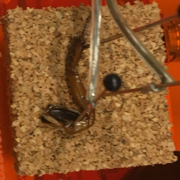

- Each recording should last about 5s 

- After recording, rename the files according to the angle of deflection, e.g. A_00.wav, A_45.wav and A_90.wav – you can go up to 180 degrees.

 Lets first clear all variables, and close all figures. 

clear amp amp_threshold ans data end_interval filename locs interval mean_freq newlocs ...
    start_interval trace wave wave_ave wave_std window x i h h2 h3 h4 h5 h6 h7
close all

Which files did you record? Enter the file names and number of the recordings in the script below.

You can add or remove the files by adding or removing the control field boxes. Alternatively, you can insert a comma after the last box and type the name of extra files in quotation marks.

filenames={'00.wav','45.wav','90.wav'};
n_recordings=3; % input the number of recordings(files to open) here

Import the data by looping through the recordings one by one (we use "for loop"). Many of the steps are very similar to importing data from the recording in the first part of the practical, so you should recognize this code by now.

h8=figure;

for i=1:n_recordings % loop through all the recordings
    filename=fullfile(folder,filenames{i}); 
    % import data for the files one by one
    data_jointangle=importdata(filename);
    data=data_jointangle.data; %import the data 
    srate=data_jointangle.fs; %import the sampling rate
    clear data_jointangle; % clear the data you are not using anymore
    
    data=data(1:floor(size(data,1)/srate)*srate,:); %cut to nearest full second
    trace=-data(:,1);%reverse polarity
   
    
    % Plot the traces
    x=(1:size(data,1))/srate;
    ax(1)=subplot(2,n_recordings,i);
    plot(x,trace);
    hold on;
    ylabel('Voltage,mV');
    title(filenames{i});
    
    % Find peaks:
    clear locs
    amp_threshold=0.05; %change amplitude threshold here!
    locs=[]; %start with an empty locs variable for each iteration through files
    [~,locs]=findpeaks(trace,'MinPeakHeight',amp_threshold,'MinPeakDistance',3); % change amplitude threshold here
    plot(x(locs),trace(locs),'ro');
    ax(2)=subplot(2,n_recordings,i+n_recordings);
    histogram(x(locs),size(trace,1)/(1*srate));
    ylabel('Spike freq, Hz');
    xlabel('Time, s');
    linkaxes(ax,'x');
    mean_freq(i)=size(locs,1)/max(x)
end % this is where the "for" loop ends. you are now through plotting all your recordings

Now let's find how the firing rate encodes different angles:

h9=figure;
angles=[0,45,90]; %input the joint angles you recorded here in degrees
plot(angles,mean_freq,'ko-','LineWidth',3);
xlabel('Joint angle, degrees');
ylabel('Spike freq, Hz');
title('joint angle encoding');

Save your figures:

saveas(h8,fullfile(folder,'Figures','Fig8_xxx.jpeg')); % change the name of the figure in the control field
saveas(h9,fullfile(folder,'Figures','Fig9_xxx.jpeg'));

***Q9: How is joint angle encoded by the sensory spikes you recorded?***

***Q10: What is rate coding?***

***Q11: For which behavioral situations might the roach need joint angle information?***

**You can take a 10 min break now. You deserved it!**

## Part 3: **Sensory stimulation** – tactile spines

###  Step 1. Sensory encoding of spine deflection direction

- While keeping your recording and stabilizing the femur-tibia joint with pins, use a tooth pick to stimulate different tactile spines:

 

- Go spine mapping: Draw a sketch of the leg and label the responsive spines on it.

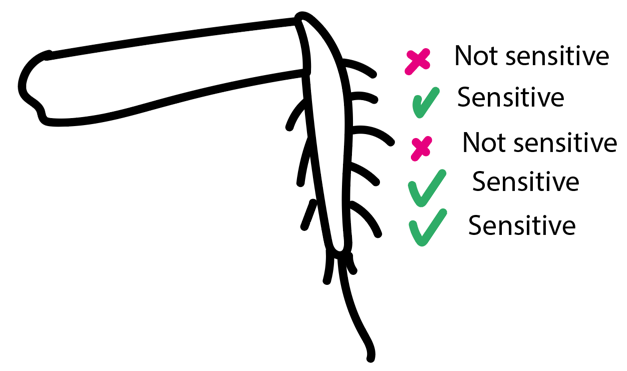

***Q12: Are some spines more responsive than others? Is there a logic to their positions?***

Choose one sensitive spine and record firing for different orientations. Use a toothpick to deflect the spine in a different direction in each recording. Name the files according to the angle of deflection, e.g.: D_00.wav, D_90.wav, D_180.wav and D_270.wav. Record 4 different deflection angles.

.

clear amp_threshold angles ax data filename filenames h8 h9 i locs mean_freq...
    n_recordings trace x
close all

 Let's input the filenames of the files you have just recorded and renamed:

Input the filenames you recorded here.

filenames={"000.wav","090.wav","180.wav","270.wav"}; 
n_recordings=4;%input the number of recordings here

Make a figure and plot the results of the frequency analysis:

h10=figure;

for i=1:n_recordings
    filename=fullfile(folder,filenames{i});
    data_orientation=importdata(filename);
    data=data_orientation.data;
    srate=data_orientation.fs;
    clear data_orientation;
    data=data(1:floor(size(data,1)/srate)*srate,:); %cut to nearest full second
    
    trace=-data(:,1);%reverse polarity
    
    % plot
    x=(1:size(data,1))/srate;
    ax(1)=subplot(2,n_recordings,i);
    plot(x,trace);
    hold on;
    ylabel('Voltage,mV');
    xlabel('Time, s')
    
    title(filenames{i});
    
    %find peaks
    amp_threshold=0.05; %change amplitude threshold here!
    locs=[]; %start with an empty locs variable for each iteration through files
    [~,locs]=findpeaks(trace,'MinPeakHeight',amp_threshold,'MinPeakDistance',3); % change amplitude threshold here
    plot(x(locs),trace(locs),'ro');
    ax(2)=subplot(2,n_recordings,i+n_recordings);
    histogram(x(locs),size(trace,1)/(1*srate));
    ylabel('Spike freq, Hz');
    xlabel('Time, s');
    linkaxes(ax,'x');
    mean_freq(i)=size(locs,1)/max(x)
end

***Q13: Look at the figures, do you see any difference between the subplots for different orientations? ***

***Q14: What do the differences mean? What are the mean frequencies for the different stimulations?***

Save the figure:

saveas(h10,fullfile(folder,'Figures','Fig10_xxx.jpeg')); % change the name of the figure in the control field

Now let's plot the sensitivity of the roach's leg to different orientaitons of the leg spines.

%Deflection angle / firing rate plot
clear x
h11=figure;
x=deg2rad([0,90,180,270]); % input the deflection angles you chose here
polarplot(x([1:end 1]),mean_freq([1:end 1]),'ko-','LineWidth',3);
hold on;
title('spine angle tuning');
rmax = max(mean_freq);
text(rmax/2, 0, 'spike freq, Hz', 'horiz', 'center', 'vert', 'top', 'rotation', 80);
text(pi/4, rmax*1.2, 'deflection angle, degrees', 'horiz', 'center', 'rotation', -45);
hold off

***Q15: is there evidence for sensitivity of the spine to a specific stimulus? What is the difference in spike frequency between the most and least sensitive angles?***

Save the figure:

saveas(h11,fullfile(folder,'Figures','Fig11_xxx.jpeg')); % change the name of the figure in the control field

### Step 2. Sensory encoding of spine deflection intensity

You can also use a toothpick to deflect the spine in one direction only, but with different force in each recording. Try this yourself! Look at the code below and change relevant lines. Name files according to the recorded files.

clear amp_threshold ax data filename filenames h10 h11 i locs mean_freq...
    n_recordings trace x
close all

% Change the names of files here to import the data from your recordings:
filenames={'soft.wav','medium.wav','hard.wav'};
h12=figure;
% Change the number of files here:
n_recordings=3;

for i=1:n_recordings
    filename=fullfile(folder,filenames{i});
    data_orientation=importdata(filename);
    data=data_orientation.data;
    srate=data_orientation.fs;
    clear  data_orientation;
    data=data(1:floor(size(data,1)/srate)*srate,:); %cut to nearest full second
    
    trace=-data(:,1);%reverse polarity
    
    % plot
    x=(1:size(data,1))/srate;
    ax(1)=subplot(2,n_recordings,i);
    plot(x,trace);
    hold on;
    ylabel('Voltage,mV');
    xlabel('Time, s')
    
    title(filenames{i});
    
    %find peaks
 
    % Change amplitude detection threshold here:
    amp_threshold=0.05; 
    locs=[]; %start with an empty locs variable for each iteration through files
    [~,locs]=findpeaks(trace,'MinPeakHeight',amp_threshold,'MinPeakDistance',3); % change amplitude threshold here
    plot(x(locs),trace(locs),'ro');
    hold off
    ax(2)=subplot(2,n_recordings,i+n_recordings);
    histogram(x(locs),size(trace,1)/(1*srate));
    ylabel('Spike freq, Hz');
    xlabel('Time, s');
    linkaxes(ax,'x');
    
    mean_freq(i)=size(locs,1)/max(x);
end

Unrecognized function or variable 'folder'.

mean_freq(i)=size(locs,1)/max(x);
saveas(h12,fullfile(folder,'Figures','Fig12_xxx.jpeg')); % change the name of the figure in the control field

%Deflection intensity vs firing rate plot
clear x

h13=figure;

% input different intensities you used:
x=[1, 2, 3];
plot(x,mean_freq,'ro-');
title('spine intensity tuning');
ylabel('Spike frequency, Hz');
xlabel('Stim intensity');

saveas(h13,fullfile(folder,'Figures','Fig13_xxx.jpeg')); % change the name of the figure in the control field

***Q16: Is the intensity of sensory stimulation coded by spike frequency?***

***Q17: What is a receptive field? How can complex receptive fields of CNS neurons arise from the simple receptive fields of sensory receptor neurons?***

## Part 4: **Sensory stimulation** – response habituation

 Here we will study how the duration of constant stimulus is encoded.

- Choose one tactile spine and stimulate it with similar short deflections of variable time durations. For example, start your recording, then stimulate for 1s, record without stimulation, finish the recording. Start another recording, record for 3s, record without stimulation, finish the recording. Make several recordings of ~15 s with different durations of stimulation in each file.

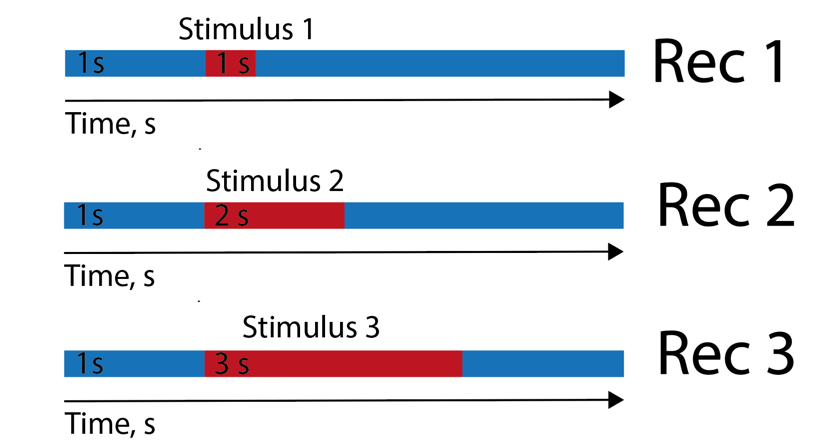

- Name the files according to the duration of deflection, e.g., short_.wav, medium.wav, long__.wav. 

clear amp_threshold ax data filename filenames h12 h13 i locs mean_freq...
    n_recordings rmax trace x
close all

Input the filenames you recorded here:

filenames={"short_.wav","medium_.wav","long_.wav"}; 

Make a figure and plot the results of your frequency analysis:

h14=figure;
n_recordings=3;%input the number of recordings here

for i=1:n_recordings
    filename=fullfile(folder,filenames{i});
    data_habituation=importdata(filename);
    data=data_habituation.data;
    srate=data_habituation.fs;
    clear data_habituation;
    data=data(1:floor(size(data,1)/srate)*srate,:); %cut to nearest full second
    
    trace=-data(:,1);%reverse polarity 
    % plot
    x=(1:size(data,1))/srate;
    ax(1)=subplot(2,n_recordings,i);
    plot(x,trace);
    hold on;
    ylabel('Voltage,mV');
    xlabel('Time, s')
    
    title(filenames{i});
    
    %find peaks
    amp_threshold=0.05; %change amplitude threshold here!
    locs=[]; %start with an empty locs variable for each iteration through files
    [~,locs]=findpeaks(trace,'MinPeakHeight',amp_threshold,'MinPeakDistance',3); % change amplitude threshold here
    plot(x(locs),trace(locs),'ro');
    ax(2)=subplot(2,n_recordings,i+n_recordings);
    histogram(x(locs),size(trace,1)/(1*srate));
    ylabel('Spike freq, Hz');
    xlabel('Time, s');
    linkaxes(ax,'x');
    rate(i).h=histcounts(x(locs),[1:1:size(trace,1)/(1*srate)]);
end

saveas(h14,fullfile(folder,'Figures','Fig14_xxx.jpeg')); % change the name of the figure in the control field

***Q18: Study the plots. Do you see the evidence of habituation (diminishing response while stimulus is still present)? What is this evidence? Which stimulus duration gives the highest habituation? ***

From your plots, how many seconds **after** the peak did the stimulus last? Input the duration in seconds for each recording below:

clear x trace
x=[1,1,6];

Now we will calculate the habituation index, how much habituation there is in the reponse. Habituation is the decrease in the response to a repeated or prolonged presentation of that stimulus. The habituation index is the ratio of number of spikes at the peak of stimulation to the number of spikes at the last second of the stimulation. The higher this index, the more habituation there is. In the example plot below the habituation index is 230/80=2.87.

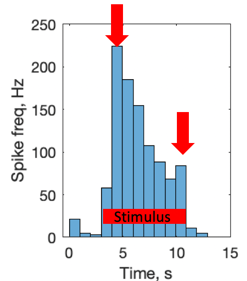

***Q19: What is habituation index during the longest stimulation?***

***Q20: What is the physiological importance of response habituation?***

Congratulations! You came to the end of the practical!

**Do not forget to save this file - **as .mlx to rerun the analysis if needed and as .docx or .pdf file to save answers to all the questions and analysis output that will be saved with the file. Also **copy all your analysis, figures and recordings** to your own memory device! You will need the figures and analysis for the report. 